## NIfTI MRS import into MATLAB

This document aims to demonstrate how magnetic resonance spectroscopy data stored according [to the proposed NIfTI MRS format specification](https://docs.google.com/document/d/1tC4ugzGUPLoqHRGrWvOcGCuCh_Dogx_uu0cxKub0EsM/edit) can be loaded into MATLAB.

First, clone the following two repositories into your MATLAB directory:

[https://github.com/wexeee/mrs_nifti_standard](https://github.com/wexeee/mrs_nifti_standard) (example data)

[https://github.com/xiangruili/dicm2nii](https://github.com/xiangruili/dicm2nii) (DICOM import/export tools)

% Find MATLAB path
pathMATLAB = userpath;

% Add data and DICOM tools
addpath(genpath([userpath filesep 'dicm2nii']));
addpath(genpath([userpath filesep 'mrs_nifti_standard']));

Define the example filename we want to load

nifti_file = 'svs_preprocessed.nii.gz';

Load the NIfTI file:

nii = nii_tool('load', nifti_file);

The resulting `nii` struct contains the data array (`img`) , NIfTI header (`hdr)`, and the MRS header extension (`ext`):

nii

nii = struct with fields:
    hdr: [1×1 struct]
    ext: [1×1 struct]
    img: [1×1×1×4096 single]


## Complex time-domain data

The complex time-domain data is stored in the `img` array, with the first three dimensions being spatial x, y and z dimensions, and the fourth dimensions being time. We can plot the single stored SV FID:

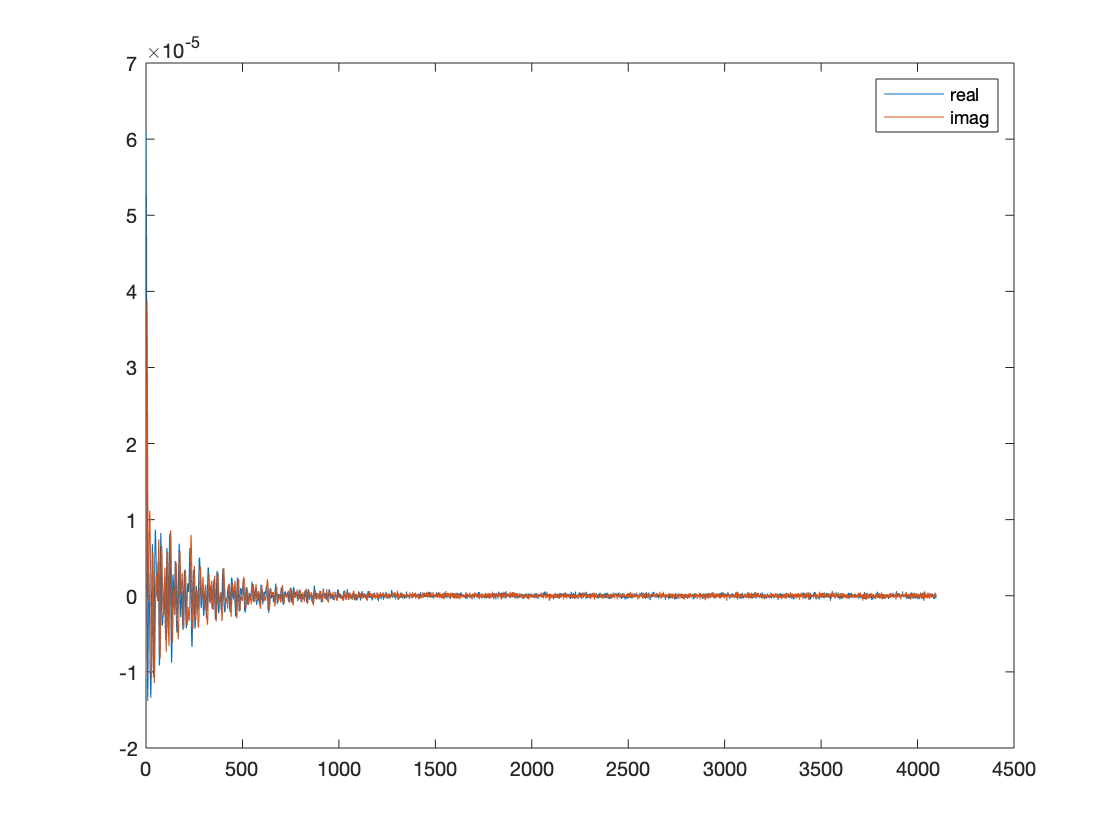

fid = squeeze(nii.img);
plot(real(fid));
hold on
plot(imag(fid));
legend('real', 'imag');
hold off

## The NIfTI header

We obviously require a few bits of information to reconstruct the frequency-domain data, most notably the dwell time and the spectrometer frequency. We find the dwell time from the standard NIfTI header:

nii.hdr

ans = struct with fields:
        sizeof_hdr: 540
             magic: 'n+2 ←↵'
          datatype: 32
            bitpix: 64
               dim: [4 1 1 1 4096 1 1 1]
         intent_p1: 0
         intent_p2: 0
         intent_p3: 0
            pixdim: [1 20 20 20 8.3300e-05 1 1 1]
        vox_offset: 848
         scl_slope: 1
         scl_inter: 0
           cal_max: 0
           cal_min: 0
    slice_duration: 0
           toffset: 0
       slice_start: 0
         slice_end: 0
           descrip: ''
          aux_file: ''
        qform_code: 2
        sform_code: 2
         quatern_b: 1
         quatern_c: 0
         quatern_d: 0
         qoffset_x: -32.9007
         qoffset_y: 10.6634
         qoffset_z: 21.3559
            srow_x: [20 0 0 -32.9007]
            srow_y: [0 -20 0 10.6634]
            srow_z: [0 0 -20 21.3559]
        slice_code: 0
        xyzt_units: 0
       intent_code: 0
       intent_name: 'mrs_v0_2'
          dim_info: 0
        unused_str: ''
         extension: [

We find the dwell time (in s) in the `pixdim` field of the NIfTI header, and can derive the spectral width:

sw = 1/nii.hdr.pixdim(5)

sw = 1.2005e+04

We also find the spatial coordinates of the MRS voxel (dimensions and offset) in the s`form` field, which we can use to create a voxel overlay mask on an anatomical image.

## The NIfTI MRS header extension

We still require the spectrometer frequency, which is stored in the header extension. We can access this JSON-formatted bit of information as follows:

% Decode the JSON header extension string
header_extension = jsondecode(nii.ext.edata_decoded)

header_extension = struct with fields:
    SpectrometerFrequency: 297.2199
          ResonantNucleus: {'1H'}
                 EchoTime: 0.0110
           RepetitionTime: 5
            InversionTime: []
               MixingTime: 0.0320
         ConversionMethod: 'Manual'
           ConversionTime: '2020-12-16T17:14:47.920'
             OriginalFile: {'meas_MID310_STEAM_metab_FID115673.dat'}


With the spectrometer frequency in MHz now known, we can create a chemical shift axis:

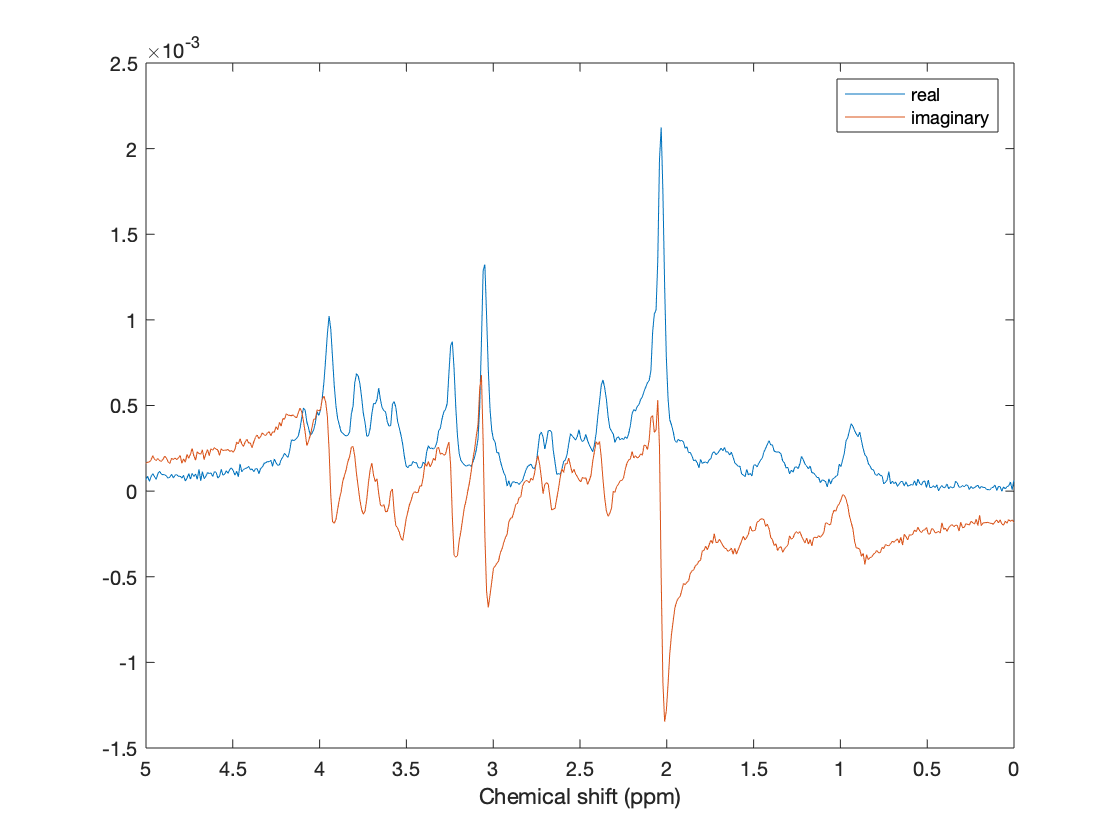

% Extract F0 and number of samples
f0 = header_extension.SpectrometerFrequency;
npts = nii.hdr.dim(5);

% Create frequency axis
f = [(-sw/2)+(sw/(2*npts)):sw/(npts):(sw/2)-(sw/(2*npts))];
% Convert to ppm
ppm = -f/f0;
ppm = ppm + 4.68;

% Calculate and plot the frequency domain spectrum
spec = fftshift(fft(fid));
plot(ppm, real(spec));
hold on;
plot(ppm, imag(spec));
set(gca, 'xdir', 'reverse', 'xlim', [0 5]);
xlabel('Chemical shift (ppm)');
legend('real', 'imag');
hold off;